# OpenAI

**Resources**

- [Introducing ChatGPT and Whisper APIs](https://openai.com/blog/introducing-chatgpt-and-whisper-apis)

- [Chat completions](https://platform.openai.com/docs/guides/chat/introduction)

## Set-up Python

pyenv(Version="env\Scripts\python.exe",ExecutionMode="OutOfProcess")

ans =   PythonEnvironment with properties:

          Version: "3.10"
       Executable: "C:\Users\ydebray\Downloads\openai\env\Scripts\python.exe"
          Library: "C:\Users\ydebray\AppData\Local\WPy64-31040\python-3.10.4.amd64\python310.dll"
             Home: "C:\Users\ydebray\Downloads\openai\env"
           Status: NotLoaded
    ExecutionMode: OutOfProcess


## Set-up OpenAI

Save OpenAI key in secrets.toml file

pythonCode = ["import tomli;"; ...
    "f = open('.streamlit\secrets.toml','rb')"; ...
    "toml_dict = tomli.load(f)"; ...
    "key = toml_dict['OPEN_AI_KEY']"; ...
    "f.close()"];
OPEN_AI_KEY = pyrun(pythonCode,"key");
% OPEN_AI_KEY = string(OPEN_AI_KEY);

Or enter the API key directly in the notebook (don't share your key with others):

% OPEN_AI_KEY = "";

Set-up the API with the key:

pyrun("import openai;openai.api_key = OPEN_AI_KEY",OPEN_AI_KEY = OPEN_AI_KEY)

## GPT 3.5 turbo

c = "The following is a conversation with an AI assistant. The assistant is helpful, creative, clever, and very friendly."; %context
p = "Hello! "; %prompt
pythonCode = ["import openai;" + ...
    "completion = openai.ChatCompletion.create(model='gpt-3.5-turbo'," ...
    "messages=[{'role': 'system','content': c},{'role': 'user','content': p}]);" ...
    "response = completion.choices[0].message.content"];
response = string(pyrun(pythonCode,"response",c=c,p=p))

response = "Hello! How may I assist you today?"

## Generate code

c = "you will give only MATLAB code as output, no explanatory text"; %context
p = "write a linear regression on a sine function"; %prompt
pythonCode = ["import openai;" + ...
    "completion = openai.ChatCompletion.create(model='gpt-3.5-turbo'," ...
    "messages=[{'role': 'system','content': c},{'role': 'user','content': p}]);" ...
    "response = completion.choices[0].message.content"];
response = string(pyrun(pythonCode,"response",c=c,p=p))

response =     "
     x = linspace(0,2*pi,100); % create x values
     y = sin(x); % create y values from sine function
     m = length(y); % length of y values
     X = [ones(m,1), x']; % design matrix
     beta = (X'*X)\X'*y'; % calculate regression coefficients
     y_hat = X*beta; % predict y values using regression coefficients
     
     plot(x,y,'bo',x,y_hat,'r-') % plot original function and regression line"


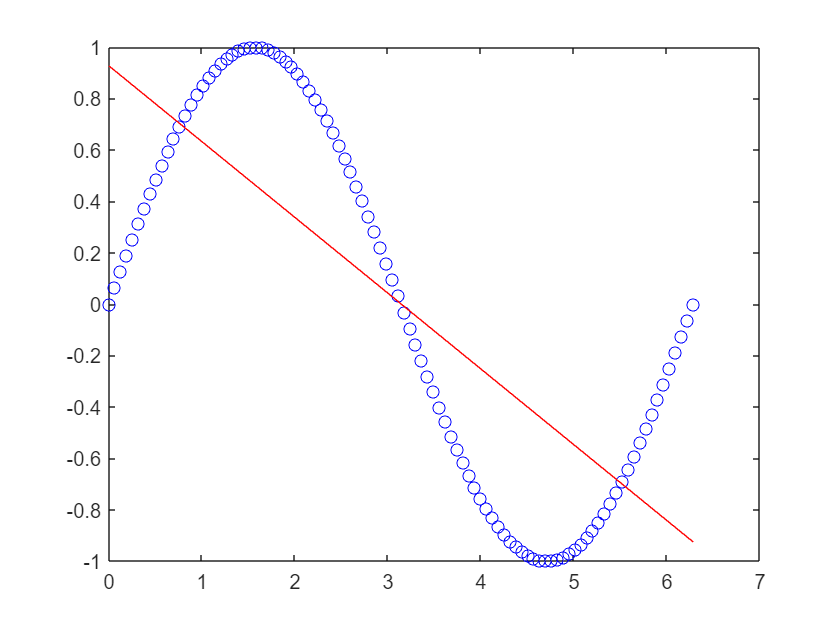

eval(response)

% Open a new file for writing
filename = 'code/code2.m';
fileID = fopen(filename, 'w');
% Write the string to the file
fprintf(fileID, '%s', response);
% Close the file
fclose(fileID);
% Open the file in the editor
edit(filename)